This script reads lab analysis and presents the location of the sample in the fields and the result

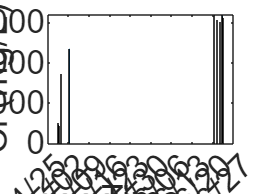

clear all
close all
opengl('save','software')
load Irrigation1sum21.txt;
Ir=Irrigation1sum21;

Irdate=x2mdate(Ir(2:15,1));ClIr=Ir(2:15,2);DPIr=Ir(2:15,3);KIr=Ir(2:15,4);SO4Ir=Ir(2:15,5);NO3Ir=Ir(2:15,6);NH4Ir=Ir(2:15,7);TNIr=Ir(2:15,8);TSSIr=Ir(2:15,9);
ECIr=Ir(2:15,10);CaMgIr=Ir(2:15,11);Caeq=Ir(2:15,12);Mgeq=Ir(2:15,13);CaIr=Ir(2:15,14);MgIr=Ir(2:15,15);TPIr=Ir(2:15,16);
Flow=Ir(:,17);Flowdate=Ir(:,18);%For P2 only
%plot(Irdate,Ir(:,2:end))
%Times of irrigation opening
OpIr1=datenum(2021,4,27,1,0,0);
OpIr2=datenum(2021,6,16,8,0,0);
OpIr3=datenum(2021,6,20,9,0,0);
OpIr4=datenum(2021,6,23,6,0,0);
OpIr11=datenum(2021,5,2,8,0,0);%Not sure, but up to 8 usually open

daysIr1=Irdate(1:4)-OpIr1;
daysIr2=Irdate(5)-OpIr11;
daysIr3=Irdate(6:12)-OpIr3;
daysIr4=Irdate(13:14)-OpIr4;
%Irdate=[daysIr1;daysIr2;daysIr3;daysIr4];
figure(1)
axes1 = axes('Parent',figure(1));
set(axes1,'FontSize',20,'XTick',...
    [738271 738273 738274 738275 738278 738285 738292 738299 738306 738313 738320 738327 738328 738329 738330 738334 738334.5 738334.75 738335],...
    'XTickLabel',...
    {'04/25','27/4','28/4','29/4','2/5','05/09','05/16','05/23','05/30','06/06','06/13','20/6','21/6','22/6','23/6','06/27','738334.5','738334.75','738335'});
bar(Irdate,ClIr)%,'.','MarkerSize',20)
datetick

xlabel('Time','FontSize',20);
set(gca,'FontSize',20)
ylabel('Cl (mg/L)')
set(gca,'FontSize',20)

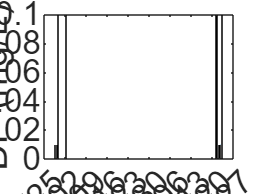



figure(2)
axes1 = axes('Parent',figure(2));
set(axes1,'FontSize',20,'XTick',...
    [738271 738273 738274 738275 738278 738285 738292 738299 738306 738313 738320 738327 738328 738329 738330 738334 738334.5 738334.75 738335],...
    'XTickLabel',...
    {'04/25','27/4','28/4','29/4','2/5','05/09','05/16','05/23','05/30','06/06','06/13','20/6','21/6','22/6','23/6','06/27','738334.5','738334.75','738335'});


bar(Irdate,DPIr)%,'.','MarkerSize',20)
%xlabel('Time','FontSize',20);set(gca,'FontSize',20)
ylabel('DP (mg/L)','FontSize',20)
datetick

set(gca,'FontSize',20)

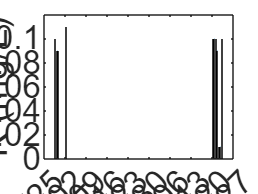


figure(3)
axes1 = axes('Parent',figure(3));
set(axes1,'FontSize',20,'XTick',...
    [738271 738273 738274 738275 738278 738285 738292 738299 738306 738313 738320 738327 738328 738329 738330 738334 738334.5 738334.75 738335],...
    'XTickLabel',...
    {'04/25','27/4','28/4','29/4','2/5','05/09','05/16','05/23','05/30','06/06','06/13','20/6','21/6','22/6','23/6','06/27','738334.5','738334.75','738335'});


bar(Irdate,KIr)%,'.','MarkerSize',20)
%xlabel('Time','FontSize',20);set(gca,'FontSize',20)
ylabel('K (mg/L)','FontSize',20)
datetick

set(gca,'FontSize',20)

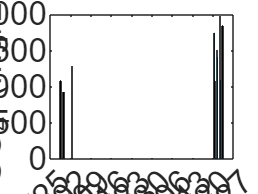


figure(4)
axes1 = axes('Parent',figure(4));
set(axes1,'FontSize',20,'XTick',...
    [738271 738273 738274 738275 738278 738285 738292 738299 738306 738313 738320 738327 738328 738329 738330 738334 738334.5 738334.75 738335],...
    'XTickLabel',...
    {'04/25','27/4','28/4','29/4','2/5','05/09','05/16','05/23','05/30','06/06','06/13','20/6','21/6','22/6','23/6','06/27','738334.5','738334.75','738335'});

bar(Irdate,SO4Ir)%,'.','MarkerSize',20)
%xlabel('Time','FontSize',20);set(gca,'FontSize',20)
ylabel('SO_4 (mg/L)','FontSize',20)
datetick

set(gca,'FontSize',20)

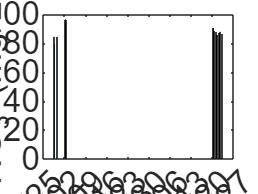


figure(5)
axes1 = axes('Parent',figure(5));
set(axes1,'FontSize',20,'XTick',...
    [738271 738273 738274 738275 738278 738285 738292 738299 738306 738313 738320 738327 738328 738329 738330 738334 738334.5 738334.75 738335],...
    'XTickLabel',...
    {'04/25','27/4','28/4','29/4','2/5','05/09','05/16','05/23','05/30','06/06','06/13','20/6','21/6','22/6','23/6','06/27','738334.5','738334.75','738335'});

bar(Irdate,NO3Ir)%,'.','MarkerSize',20)
%xlabel('Time','FontSize',20);set(gca,'FontSize',20)
ylabel('NO_3 (mg/L)','FontSize',20)
datetick

set(gca,'FontSize',20)

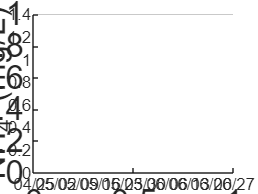


figure(6)
axes1 = axes('Parent',figure(6));
set(axes1,'FontSize',20,'XTick',...
    [738271 738273 738274 738275 738278 738285 738292 738299 738306 738313 738320 738327 738328 738329 738330 738334 738334.5 738334.75 738335],...
    'XTickLabel',...
    {'04/25','27/4','28/4','29/4','2/5','05/09','05/16','05/23','05/30','06/06','06/13','20/6','21/6','22/6','23/6','06/27','738334.5','738334.75','738335'});

bar(Irdate,NH4Ir)%,'.','MarkerSize',20)
%xlabel('Time','FontSize',20);set(gca,'FontSize',20)
ylabel('NH_4 (mg/L)','FontSize',20)
datetick
axes1 = axes('Parent',figure(6));

set(gca,'FontSize',20)

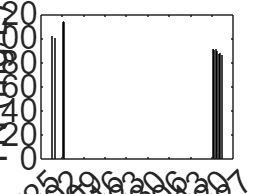


figure(7)
axes1 = axes('Parent',figure(7));
set(axes1,'FontSize',20,'XTick',...
    [738271 738273 738274 738275 738278 738285 738292 738299 738306 738313 738320 738327 738328 738329 738330 738334 738334.5 738334.75 738335],...
    'XTickLabel',...
    {'04/25','27/4','28/4','29/4','2/5','05/09','05/16','05/23','05/30','06/06','06/13','20/6','21/6','22/6','23/6','06/27','738334.5','738334.75','738335'});

bar(Irdate,TNIr)%,'.','MarkerSize',20)
%xlabel('Time','FontSize',20);set(gca,'FontSize',20)
ylabel('TN (mg/L)','FontSize',20)
datetick

set(gca,'FontSize',20)

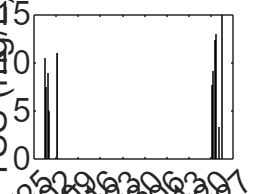


figure(8)
axes1 = axes('Parent',figure(8));
set(axes1,'FontSize',20,'XTick',...
    [738271 738273 738274 738275 738278 738285 738292 738299 738306 738313 738320 738327 738328 738329 738330 738334 738334.5 738334.75 738335],...
    'XTickLabel',...
    {'04/25','27/4','28/4','29/4','2/5','05/09','05/16','05/23','05/30','06/06','06/13','20/6','21/6','22/6','23/6','06/27','738334.5','738334.75','738335'});

bar(Irdate,TSSIr)%,'.','MarkerSize',20)
%xlabel('Time','FontSize',20);set(gca,'FontSize',20)
ylabel('TSS (mg/L)','FontSize',20)
datetick

set(gca,'FontSize',20)

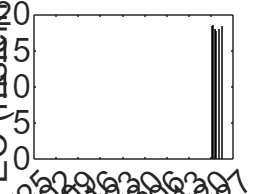


figure(9)
axes1 = axes('Parent',figure(9));
set(axes1,'FontSize',20,'XTick',...
    [738271 738273 738274 738275 738278 738285 738292 738299 738306 738313 738320 738327 738328 738329 738330 738334 738334.5 738334.75 738335],...
    'XTickLabel',...
    {'04/25','27/4','28/4','29/4','2/5','05/09','05/16','05/23','05/30','06/06','06/13','20/6','21/6','22/6','23/6','06/27','738334.5','738334.75','738335'});

bar(Irdate,ECIr)%,'.','MarkerSize',20)
%xlabel('Time','FontSize',20);set(gca,'FontSize',20)
ylabel('EC (msiem)','FontSize',20)
datetick

set(gca,'FontSize',20)

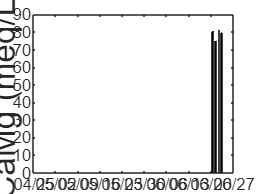


figure(10)
axes1 = axes('Parent',figure(10));
set(axes1,'FontSize',20,'XTick',...
    [738271 738273 738274 738275 738278 738285 738292 738299 738306 738313 738320 738327 738328 738329 738330 738334 738334.5 738334.75 738335],...
    'XTickLabel',...
    {'04/25','27/4','28/4','29/4','2/5','05/09','05/16','05/23','05/30','06/06','06/13','20/6','21/6','22/6','23/6','06/27','738334.5','738334.75','738335'});

bar(Irdate,CaMgIr)%,'.','MarkerSize',20)
%xlabel('Time','FontSize',20);set(gca,'FontSize',20)
ylabel('CaMg (meq/L)','FontSize',20)
datetick

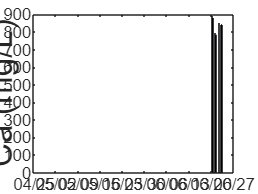




figure(11)
axes1 = axes('Parent',figure(11));
set(axes1,'FontSize',20,'XTick',...
    [738271 738273 738274 738275 738278 738285 738292 738299 738306 738313 738320 738327 738328 738329 738330 738334 738334.5 738334.75 738335],...
    'XTickLabel',...
    {'04/25','27/4','28/4','29/4','2/5','05/09','05/16','05/23','05/30','06/06','06/13','20/6','21/6','22/6','23/6','06/27','738334.5','738334.75','738335'});

bar(Irdate,CaIr)%,'.','MarkerSize',20)
%xlabel('Time','FontSize',20);set(gca,'FontSize',20)
ylabel('Ca (mg/L)','FontSize',20)
datetick

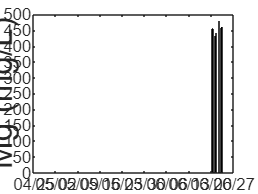



figure(12)
axes1 = axes('Parent',figure(12));
set(axes1,'FontSize',20,'XTick',...
    [738271 738273 738274 738275 738278 738285 738292 738299 738306 738313 738320 738327 738328 738329 738330 738334 738334.5 738334.75 738335],...
    'XTickLabel',...
    {'04/25','27/4','28/4','29/4','2/5','05/09','05/16','05/23','05/30','06/06','06/13','20/6','21/6','22/6','23/6','06/27','738334.5','738334.75','738335'});

bar(Irdate,MgIr)%,'.','MarkerSize',20)
%xlabel('Time','FontSize',20);set(gca,'FontSize',20)
ylabel('Mg (mg/L)','FontSize',20)
datetick

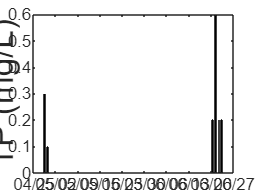



figure(13)
axes1 = axes('Parent',figure(13));
set(axes1,'FontSize',20,'XTick',...
    [738271 738273 738274 738275 738278 738285 738292 738299 738306 738313 738320 738327 738328 738329 738330 738334 738334.5 738334.75 738335],...
    'XTickLabel',...
    {'04/25','27/4','28/4','29/4','2/5','05/09','05/16','05/23','05/30','06/06','06/13','20/6','21/6','22/6','23/6','06/27','738334.5','738334.75','738335'});

bar(Irdate,TPIr)%,'.','MarkerSize',20)
%xlabel('Time','FontSize',20);set(gca,'FontSize',20)
ylabel('TP (mg/L)','FontSize',20)
datetick

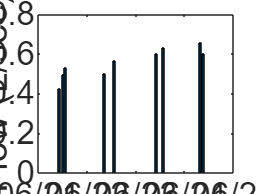



figure(14)
axes1 = axes('Parent',figure(14));
set(axes1,'FontSize',20,'XTick',...
    [738271 738273 738274 738275 738278 738285 738292 738299 738306 738313 738320 738327 738328 738329 738330 738334 738334.5 738334.75 738335],...
    'XTickLabel',...
    {'04/25','27/4','28/4','29/4','2/5','05/09','05/16','05/23','05/30','06/06','06/13','20/6','21/6','22/6','23/6','06/27','738334.5','738334.75','738335'});

bar(Flowdate,Flow)%,'.','MarkerSize',20)
datetick

%xlabel('Time','FontSize',20);
set(gca,'FontSize',20)
ylabel('Flow (L/sec)')
set(gca,'FontSize',20)